[file_loc] = fileparts(matlab.desktop.editor.getActiveFilename);
cd(file_loc);

C194 = readmatrix(fullfile(pwd(),"\C194\outmat.txt"));
C198 = readmatrix(fullfile(pwd(),"\C198\outmat.txt"));
C200 = readmatrix(fullfile(pwd(),"\C200\outmat.txt"));
allDat = cat(3,C194,C198,C200);
meanDat = mean(allDat,3);
semDat = std(allDat,[],3)/sqrt(3);

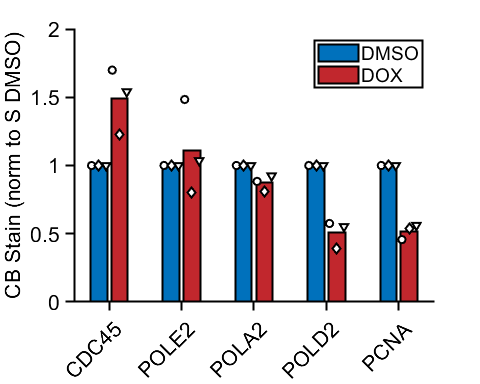

shapes = ['odv'];
jit = 0.3*(rand(3,1)-.5);
jit = [-.1 0 .1];
colors = [0 113 188; 193 39 45]/255;

figure('Units', 'Inches', 'Position', [0, 0, 5, 4]), hold on
b = bar(meanDat,'LineWidth',1.5);
b(1).FaceColor = colors(1,:);
b(2).FaceColor = colors(2,:);
xloc = b(1).XEndPoints;
% errorbar(xloc,meanDat(:,1),2*semDat(:,1),'k.','LineWidth',1.5)
for i=1:size(allDat,3)
    for j = 1:size(allDat,1)
        s(j) = scatter(xloc(j)+jit(i),allDat(j,1,i),30,shapes(i),'k','LineWidth',1.5,'MarkerFaceColor','w');
    end
%     set(gca,'ColorOrderIndex',1)
end

xloc = b(2).XEndPoints;
% errorbar(xloc,meanDat(:,2),2*semDat(:,2),'k.','LineWidth',1.5)
for i=1:size(allDat,3)
    for j = 1:size(allDat,1)
        s(j) = scatter(xloc(j)+jit(i),allDat(j,2,i),30,shapes(i),'k','LineWidth',1.5,'MarkerFaceColor','w');
    end
%     set(gca,'ColorOrderIndex',1)
end

% pbaspect([1 1 1])
% legend(s,{'Rep. 1','Rep. 2','Rep. 3'},'FontSize',10,'Box','off','Location','northwest')
legend({'DMSO','DOX'})
ylabel('CB Stain (norm to S DMSO)')
% ylim([0 1.1])
xticks([1:5])
% xlim([0 3])
xticklabels({'CDC45','POLE2','POLA2','POLD2','PCNA'})
xtickangle(45)
print_pdf([pwd() '\Figs\replicate_bar.pdf'])

for i = 1:size(allDat,1)
    data = squeeze(allDat(i,2,:));
    [h,p,ci,~] = ttest(data-1)
end

h = 0

p = 0.0712

ci =    -0.1048
    1.0833


h = 0

p = 0.6442

ci =    -0.7519
    0.9670


h = 0

p = 0.0635

ci =    -0.2736
    0.0179


h = 1

p = 0.0138

ci =    -0.7469
   -0.2415


h = 1

p = 0.0044

ci =    -0.6177
   -0.3434


C194 = readmatrix(fullfile(pwd(),"\C194\ratios.txt"));
C198 = readmatrix(fullfile(pwd(),"\C198\ratios.txt"));
C200 = readmatrix(fullfile(pwd(),"\C200\ratios.txt"));
allDat = cat(2,C194',C198',C200');
meanDat = mean(allDat,2);
semDat = std(allDat,[],2)/sqrt(3);

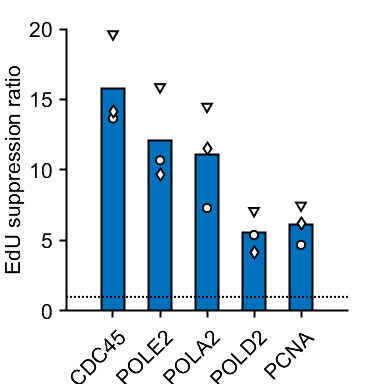

shapes = ['odv'];
jit = 0.3*(rand(3,1)-.5);
jit = [-.2 0 .2];
jit = [0 0 0];
colors = [0 113 188; 193 39 45]/255;

figure('Units', 'Inches', 'Position', [0, 0, 4, 4]), hold on
b = bar(meanDat,.5,'LineWidth',1.5);
xloc = 1:size(meanDat);
% errorbar(xloc,meanDat(:,1),2*semDat(:,1),'k.','LineWidth',1.5)
for i=1:size(allDat,2)
    for j = 1:size(allDat,1)
        s(j) = scatter(xloc(j)+jit(i),allDat(j,i),40,shapes(i),'k','LineWidth',1.5,'MarkerFaceColor','w');
    end
%     set(gca,'ColorOrderIndex',1)
end

axis square
ylabel('EdU suppression ratio')
% ylim([0 1.1])
xticks([1:5])
% xlim([0 3])
hline(1,'k:')
xticklabels({'CDC45','POLE2','POLA2','POLD2','PCNA'})
xtickangle(45)
print_pdf([pwd() '\Figs\replicate_bar_slopes.pdf'])

for i = 1:size(allDat,1)
    data = allDat(i,:);
    [h,p,ci,~] = ttest(data-1)
end

h = 1

p = 0.0164

ci =     6.5326   23.0759


h = 1

p = 0.0286

ci =     2.8404   19.3481


h = 1

p = 0.0401

ci =     1.1315   19.0807


h = 1

p = 0.0341

ci =     0.8392    8.2477


h = 1

p = 0.0240

ci =     1.6484    8.6086
